% figure
% gm= importGeometry(".\models\LoftedSurface v2.stl"); % input
% pdegplot(gm)

global noperpPoints;
noperpPoints = 0;
global totalSuchPoints;
totalSuchPoints = 0;
% clear
[modelT,~,~,~] = stlread(".\models\part3Surface v9.stl");
% start_point = [-68 0 0];
% end_point = [35 0 0];
preformAngle = 70;
pointsPerFacet = 20;
angleDif = 1;
sectionPoint = [0 0 0];
[sectionPoints2,preformedSectionPoints2,colors2,preformColors2] = preformSectionPoints(modelT,sectionPoint,angleDif,preformAngle,pointsPerFacet);

Mapping facets to deltas...
Shifting original points for each delta of the section...
point lists formed!


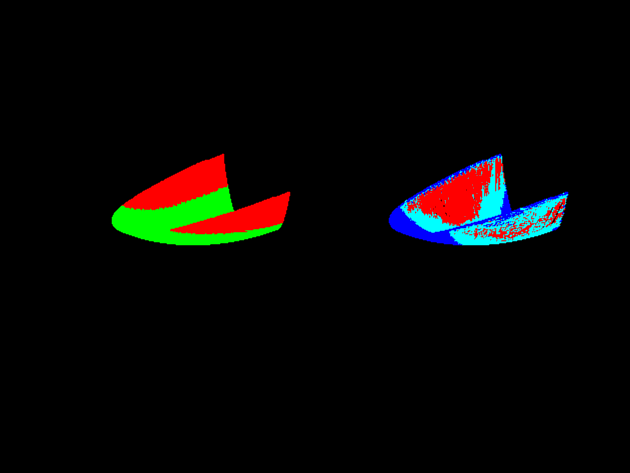

ptCld = pointCloud(sectionPoints2,Color=colors2);
ptCld2 = pointCloud(preformedSectionPoints2,Color = preformColors2);
figure
subplot(1,2,1);
pcshow(ptCld);
subplot(1,2,2);
pcshow(ptCld2);

% v = [0 0 0; 1 0 0; 0 1 0];
% randPointsOnFacet([v v],10)
x = [1 2;3 4;5 6];
x = x-4

x =     -3    -2
    -1     0
     1     2


x(x>0)

ans =      1
     2


x(x(:,2)>0)

ans = 1

% if((all(x > -7) || all(x < 3)))
%     disp("Hi")
% else
%     disp("no")
% end
noperpPoints

noperpPoints = 0

totalSuchPoints

totalSuchPoints = 99916

disp(noperpPoints*100/totalSuchPoints)

     0



function [sectionPoints,preformedSectionPoints,colors,preformColors] = preformSectionPoints(modelT,sectionPoint,angleDif,performAngle,pointsPerFacet)
    totalFacets = size(modelT.ConnectivityList,1);
    totalDeltas = 360/angleDif;
    avgFacetsPerDelta = round(totalFacets); 
    deltaFacetMap = zeros(totalDeltas,avgFacetsPerDelta); % each row represents a delta, which has the IDs of facet present
    facetsofDelta = zeros(totalDeltas); % contains number of deltas in each facet

    disp("Mapping facets to deltas...")
    for facet=1:totalFacets
        v1 = modelT.Points(modelT.ConnectivityList(facet,1),:); %delta allocation by 1st vertex of the facet
        angle = atan2d((v1(2)-sectionPoint(2)),(v1(1)-sectionPoint(1)));
        if(angle == 180)
            angle =  -180;
        end
        delta = floor((angle+180)/angleDif)+1;
        idx = facetsofDelta(delta)+1;
        deltaFacetMap(delta,idx) = facet;
        facetsofDelta(delta) = idx;
    end
    
    totalPoints = size(modelT.ConnectivityList,1)*pointsPerFacet;
    sectionPoints = ones(totalPoints,3); preformedSectionPoints = ones(totalPoints,3);
    colors = zeros(totalPoints,3); preformColors = zeros(totalPoints,3);
    currentPoint = 0;

    disp("Shifting original points for each delta of the section...")
    for angle= -180:angleDif:180-angleDif %=start angle
        delta = floor((angle+180)/angleDif)+1;
%         disp(angle)
        [dp,pdp,clr,pfclr] = preformDeltaPoints(modelT,deltaFacetMap(delta,:),facetsofDelta(delta),performAngle,pointsPerFacet);
        if(facetsofDelta(delta) == 0)
            disp(["no facets for angle" angle])
            continue
        end
        sectionPoints(currentPoint+1:currentPoint+size(clr),:) = dp;
        preformedSectionPoints(currentPoint+1:currentPoint+size(clr),:) = pdp;
        colors(currentPoint+1:currentPoint+size(clr),:) = clr;
        preformColors(currentPoint+1:currentPoint+size(clr),:) = pfclr;
        currentPoint = currentPoint + size(dp,1);
    end
    disp("point lists formed!")


    return

end

### `preformSectionPoints `(for exturuded section):

Assumptions:

- The tool comes along z-axis, the surface is extruded along y-axis

Algorithm:

- find the extrema points on either sides `(p1,p2)` of the section where the wall angle,$\theta >\alpha ,$preform angle.

- for each facet in the section, put a fixed number of random points

- for each point :   

                   if it is before `p1 `or `p2 `leave it **as is**

                   if it is after `p1 or p2 `and the projected cone surface is above the original surface, **shift ** it to the cone surface

                  if it is after `p1 or p2 `and the projected cone surface is below the original surface, stop assigning cone surface and

                  **shift** it to a flat horizontal surface. Where the horizontal surface is the z-plane that has the hightest point which suits

                 the above criterion.

function [deltaPoints,preformedDeltaPoints,colors,preformedColors] = preformDeltaPoints(modelT,facetIDs,totalFacets,preformAngle,pointsPerFacet)
     
     
     preformedDeltaPoints = ones(pointsPerFacet*totalFacets,3)*Inf;
     deltaPoints = ones(pointsPerFacet*totalFacets,3);

     green = [0 255 0]; %default color
     colors =  repmat(green,pointsPerFacet*totalFacets,1);
     preformedColors =  repmat(green,pointsPerFacet*totalFacets,1);

     if(totalFacets == 0)
         return
     end

     facetNormals = faceNormal(modelT,facetIDs(1:totalFacets)');
     steepFacetIndices = find(acosd(facetNormals(:,3)) > preformAngle); %index of steep facets in FacetIDs
     p1 = ones(1,3)*-Inf;
     
     for i = 1:size(steepFacetIndices,1)
        v = modelT.Points(modelT.ConnectivityList(facetIDs(steepFacetIndices(i)),:),:);
        v = sortrows(v,3,"ascend");
        if(p1(3) < v(1,3))
            p1 = v(1,:);
        end
        %red color for steepFacet points(for final surface)
        colors((steepFacetIndices(i)-1)*pointsPerFacet+1:steepFacetIndices(i)*pointsPerFacet,:) = repmat([255 0 0],pointsPerFacet,1);
     end
     
     %%%%%%%%%% smallest distance consideration
%      intersectingFacets = facetIDs(isIntersectingFacets(modelT,facetIDs(1:totalFacets),p1));
%      if(~isempty(steepFacetIndices) && isempty(intersectingFacets))
%          disp("->No intersecting facets!!")
%      end 
     %%%%%%%%%%


     z_max = -1*Inf;
     for i = 1:totalFacets
        v = modelT.Points(modelT.ConnectivityList(facetIDs(i),:),:); 
        randPoints = randPointsOnFacet(v,pointsPerFacet);
        deltaPoints((i-1)*pointsPerFacet+1:(i)*pointsPerFacet,:) = randPoints;

        for pt=1:pointsPerFacet % z_cone calculation  % for sections with no local maxima
            if(p1(3) >= randPoints(pt,3))
%                 dist = nearestDistInDelta(modelT,intersectingFacets,p1,randPoints(pt));
%                 z = p1(3)-dist*tand(preformAngle);
                z = p1(3)-sqrt(((randPoints(pt,1)-p1(1))^2)+((randPoints(pt,2)-p1(2))^2))*tand(preformAngle);
%                 if(sqrt(((randPoints(pt,1)-p1(1))^2)+((randPoints(pt,2)-p1(2))^2)) >= dist)
%                     disp("Hey you have some error here")
%                 end
            else % the point is before the region where preform = final form
                preformedDeltaPoints((i-1)*pointsPerFacet+pt,:) = randPoints(pt,:);
                preformedColors((i-1)*pointsPerFacet+pt,:) = [0 0 255];              %'blue'
                continue
            end

%             preformedDeltaPoints((i-1)*pointsPerFacet+pt,:) = randPoints(pt,:);
%             preformedDeltaPoints((i-1)*pointsPerFacet+pt,3) = z;
%             preformedColors((i-1)*pointsPerFacet+pt,:) = [255 0 0];      %'red';
            
            if(z >= randPoints(pt,3)) % cone should be put
                preformedDeltaPoints((i-1)*pointsPerFacet+pt,:) = randPoints(pt,:);
                preformedDeltaPoints((i-1)*pointsPerFacet+pt,3) = z;
                preformedColors((i-1)*pointsPerFacet+pt,:) = [255 0 0];      %'red';
            else % donot update the preform and leave as Inf => crossing points
                z_max = max(randPoints(pt,3),z_max);
                  preformedDeltaPoints((i-1)*pointsPerFacet+pt,:) = randPoints(pt,:);
                  preformedColors((i-1)*pointsPerFacet+pt,:) = [0 255 255];      %'cyan';
            end
        end   
     end

%      cnt = 0;
% 
%      if(z_max ~= Inf*-1) %%some correction needed here
% %          disp("Preform was on top")
%          for pt = 1:size(preformedDeltaPoints,1)
%              if(preformedDeltaPoints(pt,3) == Inf)
%                  preformedDeltaPoints(pt,:) = deltaPoints(pt,:);
%                  preformedDeltaPoints(pt,3) = z_max;
%                  preformedColors(pt,:) = [0 255 255]; % 'cyan'
%                  cnt = cnt+1;
%              end
%          end
%      end
%        disp("------------------------")
    
     return
end


### `isFacetInSection `(for extruded section):

Assumptions:

- The surface is extruded along y-axis

- The stl file contains a *surface, not solid*

Algorithm:

- The facet belongs to the section if all 3 veritces of the facet are within the x-limits of the section

function [inSection,vertices] = isFacetInSection(modelT,sectionPoint,startAngle,endAngle,facetID)
      inSection = true;
      vertices = zeros(3,3);
      facenormal = faceNormal(modelT,facetID);
      if(facenormal(3) <= 0) % ignore outer facets
        inSection = false;
        return
      end

     v1 = modelT.Points(modelT.ConnectivityList(facetID,1),:);
     v2 = modelT.Points(modelT.ConnectivityList(facetID,2),:);
     v3 = modelT.Points(modelT.ConnectivityList(facetID,3),:);

     angle = atan2d((v1(2)-sectionPoint(2)),(v1(1)-sectionPoint(1)));
     if(angle < startAngle(1) ||  angle > endAngle(1))
        inSection = false;
        return
     end

     v = [v1; v2; v3];
     vertices = sortrows(v,3,"descend");
end


### `randPointsOnFacet`

Assumptions:

- Any triangle in 3D

Algorithm:

- $\alpha *\vec{\textrm{v1}} +\beta *\vec{\textrm{v2}} +\gamma *\vec{\textrm{v3}} =\vec{p} \;$is a point in triagle with vertices $\vec{\textrm{v1}} ,\vec{\textrm{v2}} \;\textrm{and}\;\vec{\textrm{v3}}$, where $\alpha +\beta +\gamma =1\;\textrm{for}\;\textrm{positive}\;\textrm{values}\;\textrm{of}\;\alpha ,\beta ,\gamma$

function [randPoints] = randPointsOnFacet(vertices,pointsPerFacet)
    randPoints = zeros(pointsPerFacet,3);
    
    for j = 1:pointsPerFacet  % create certain number of random points inside the facet
        a = rand();
        b = rand();
        if (a+b > 1)
            a = 1-a;
            b = 1-b;
        end
        pnt = vertices(1,:)*a+vertices(2,:)*b+vertices(3,:)*(1-a-b);
        randPoints(j,:) = pnt;
    end

end

a

function [isInterFacets] = isIntersectingFacets(modelT,facetIDs,point1)
    isInterFacets = true(size(facetIDs,2),1);
    z = point1(3);
    for facet = 1:size(facetIDs,2)
        verticesZ = modelT.Points(modelT.ConnectivityList(facetIDs(facet),:),3);
        verticesZ = verticesZ-z;
%         if(facetIDs(facet) == bfid)
%             disp(["->best facet: (z)" z])
%             disp(verticesZ)
%         end
        if (all(verticesZ <0) || all(verticesZ >0))
            isInterFacets(facet) = false;
        end
    end

end

b

% function [dist] = nearestDistInDelta(modelT,facetIDs,point1,point)
%     normals = faceNormal(modelT,facetIDs');
%     planePoints = modelT.Points(modelT.ConnectivityList(facetIDs,1),:);
%     point(3) = point1(3);
%     dist = Inf;
%     for i=1:size(facetIDs,2)
%         di = dot(normals(i,:),planePoints(i,:));
%         pi = dot(normals(i,:),point);
%         den = sqrt((normals(i,1)^2)+(normals(i,2)^2));
%         d = abs(pi - di)/den;
%         dist = min(dist,d);
%     end
% %     disp(dist)
% end


function [dist] = nearestDistInDelta(modelT,facetIDs,point1,point)
    global noperpPoints;
    global totalSuchPoints;
    totalSuchPoints = totalSuchPoints +1;
    normals = faceNormal(modelT,facetIDs');
    planePoints = modelT.Points(modelT.ConnectivityList(facetIDs,1),:);
    dist = Inf;
    dif = Inf;
    point(3) = point1(3);
    for i=1:size(facetIDs,2)
        a = normals(i,1); b = normals(i,2); c = normals(i,3);
        D = dot(normals(i,:),planePoints(i,:))-c*point1(3);
        den = sqrt(a^2+b^2);
        x = (a*D+(b^2)*point(1)-a*b*point(2))/den;
        y = (b*D+(a^2)*point(2)-a*b*point(1))/den;
        projectionPoint = [x y point1(3)];
        areaDif = isPointInsideFacet(projectionPoint,modelT.Points(modelT.ConnectivityList(facetIDs(i),:),:));
        dif = min(dif,areaDif);
%         if(areaDif == 0)
            d = norm(projectionPoint-point);
            dist = min(dist,d);
%         end
    end
    if(dist  == Inf)
        noperpPoints = noperpPoints +1;
    end
end


function [inside] = isPointInsideFacet(point,vertices) %modifying to give % area dif
    a = areaTriangle(vertices(1,:),vertices(2,:),vertices(3,:));
    a1 = areaTriangle(point,vertices(2,:),vertices(3,:));
    a2 = areaTriangle(vertices(1,:),point,vertices(3,:));
    a3 = areaTriangle(vertices(1,:),vertices(2,:),point);

    inside = abs(a1+a2+a3-a)/a;
end

function [area] =  areaTriangle(v1,v2,v3)
    AB = v1-v2; AC = v2-v3;
    area = 0.5*norm(cross(AB,AC));
end